## **creacion de un robot usando los parametros de  DHmod**

definicion de parametros

%definiciones 
L1num=2;
L2num=2;


para crear el robot se utiliza el toolbox de peter corke (v 9.10). el primer paso es **la creacion de los eslabones** (links) a partir de la tabla de parametros DHmod

los eslabones se crean con la funcio (link)

Link('tipo_de_junta','alpha',valor,'a',valor,'d',valor,'theta',valor,'offset',valor,'modified')

**Aclaraciones**

- tipos de junta->>'revolute'=R, 'prismatic'=p

- si la junta es R no hay que especificar 'theta'

- si la junta es P no hay que especificar 'd'

- 'modified ' es para aclarar que la notacion es modificada 

L(1) = Link('revolute','alpha',0,'a',0,'d',0,'modified'); %eslabon 1 --> fila 1 
L(2) = Link('revolute','alpha',0,'a',L1num,'d',0,'modified'); %eslabon 2 --> fila 2
L

 
L = 
 theta=q1, d=          0, a=          0, alpha=          0, offset=          0 (R,modDH)
 theta=q2, d=          0, a=          2, alpha=          0, offset=          0 (R,modDH)


**Creacion del mecanismo **

una vez creadas los eslabones, se utiliza la funcion SerialLink() para unir los eslabones del manipulador serial 

%unir links 'eslabones'
RR = SerialLink(L,'name','Robot 2R')

 
RR = 
 
Robot 2R (2 axis, RR, modDH, fastRNE)                            
                                                                 
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|          0|          0|          0|
|  2|         q2|          0|          2|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
                                                                 
grav =    0  base = 1  0  0  0   tool =  1  0  0  0              
          0         0  1  0  0           0  1  0  0              
       9.81         0  0  1  0           0  0  1  0              
                    0  0  0  1           0  0  0  1              
 


Definir herramienta: para esto se usa la matriz $T_{\textrm{tool}}$ 

%agregar herramienta del robot 
RR.tool = transl(L2num,0,0);
RR

 
RR = 
 
Robot 2R (2 axis, RR, modDH, fastRNE)                            
                                                                 
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|          0|          0|          0|
|  2|         q2|          0|          2|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
                                                                 
grav =    0  base = 1  0  0  0   tool =  1  0  0  2              
          0         0  1  0  0           0  1  0  0              
       9.81         0  0  1  0           0  0  1  0              
                    0  0  0  1           0  0  0  1              
 


**Graficar Robot **

se usa la funcion plot() del objeto SerialLink()

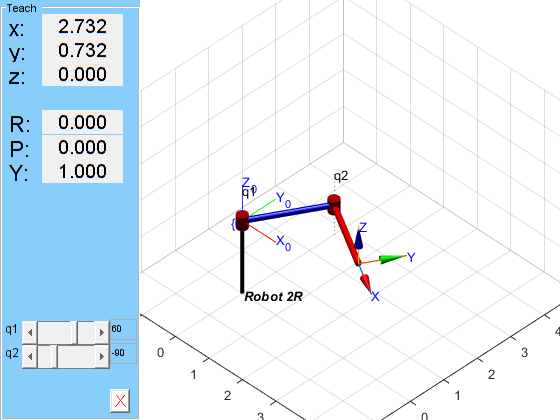

% 1 configuracion 
q = [pi/3 -pi/2]; %rotamos  q1->60°  y q2->-90° la herramienta queda orientada a -30° 
RR.plot(q,'notiles','scale',0.7, 'jaxes') %dibujar el robot
hold on 
trplot(eye(4),'rgb','length',1,'frame','0') % sistema coordenadas de la base 
axis([-2 5 -2 5 -2 3])% ajusta los ejes 
view(45, 40)% vista frente 
RR.teach()

syms q1 q2 %%variables simbolicas 
T01 = L(1).A(q1)%% MTh del sistema de coordenada 1 respecto al sistema 0

$$T01 = \left(\begin{array}{cccc} \cos\left(q_{1}\right) & -\sin\left(q_{1}\right) & 0 & 0\\ \sin\left(q_{1}\right) & \cos\left(q_{1}\right) & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T12 = L(2).A(q2)% MTh del sistema de coordenada 2 respecto al sistema 1

$$T12 = \left(\begin{array}{cccc} \cos\left(q_{2}\right) & -\sin\left(q_{2}\right) & 0 & 2\\ \sin\left(q_{2}\right) & \cos\left(q_{2}\right) & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T02 = simplify(T01*T12)%MTH del sistemas de coordendas 2 respecto al sistema 0 simplificada

$$T02 = \left(\begin{array}{cccc} \cos\left(q_{1}+q_{2}\right) & -\sin\left(q_{1}+q_{2}\right) & 0 & 2\,\cos\left(q_{1}\right)\\ \sin\left(q_{1}+q_{2}\right) & \cos\left(q_{1}+q_{2}\right) & 0 & 2\,\sin\left(q_{1}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T23 = RR.tool %Mth de la herramienta  sistema 3 respecto 2

T23 =      1     0     0     2
     0     1     0     0
     0     0     1     0
     0     0     0     1


T03 = simplify(T01*T12*T23)%matriz de cinematica directa del robot

$$T03 = \left(\begin{array}{cccc} \cos\left(q_{1}+q_{2}\right) & -\sin\left(q_{1}+q_{2}\right) & 0 & 2\,\cos\left(q_{1}+q_{2}\right)+2\,\cos\left(q_{1}\right)\\ \sin\left(q_{1}+q_{2}\right) & \cos\left(q_{1}+q_{2}\right) & 0 & 2\,\sin\left(q_{1}+q_{2}\right)+2\,\sin\left(q_{1}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

%prueba de la cinematica: 1 configuracion
double(subs((T03),[q1,q2],[pi/3,-pi/2]))%se remplaza en 3 respecto a 

ans =     0.8660    0.5000         0    2.7321
   -0.5000    0.8660         0    0.7321
         0         0    1.0000         0
         0         0         0    1.0000
